% ========================================================
% === SCRIPT COMPLETO (pipeline finale - Yale CNN) =======
% ========================================================
clear; clc; close all;

%% 1) HYPER-PARAMETERS
epochs       = 100;      % lasciamo correre (early-stop)
base_lr      = 0.05;     % learning-rate alto per “svegliare” la rete
lambda       = 0;        % L2 OFF (riattivala dopo il sanity-check)
dropout_rate = 0;        % dropout OFF (id.)
batch_size   = 32;
patience     = 10;       % early-stopping su validation
debug_batch  = true;     % stampa solo 1° mini-batch del 1° epoch

%% 2) LOAD YALE DATASET (senza toolbox)
load('dataset/volti_dataset_Yale.mat');   % variabili: A (m×n)  labels
img_h = 112;  img_w = 92;
A      = double(A) / 255;
labels = labels(:);
num_classes = max(labels);

% ---------- normalizzazione per-pixel (zero-mean / unit-std) ----------
imgs_raw = reshape(A, img_h, img_w, []);      % [112×92×400]
mean_img = mean(imgs_raw, 3);
std_img  = std(imgs_raw, 0, 3) + eps;
imgs     = (imgs_raw - mean_img) ./ std_img;  % immagini normalizzate

%% 3) SPLIT 5-vs-5  (train / test)
train_idx = [];  test_idx = [];
for s = 1:num_classes
    idx = find(labels == s);
    idx = idx(randperm(numel(idx)));
    train_idx = [train_idx; idx(1:5)];
    test_idx  = [test_idx;  idx(6:end)];
end
imgs_train_base = imgs(:, :, train_idx);
y_train_base    = labels(train_idx)';
imgs_test       = imgs(:, :, test_idx);
y_test          = labels(test_idx)';

%% 4) DATA-AUGMENTATION (+ split validation 20 %)
[imgs_train_aug, y_train_aug] = augment_data(imgs_train_base, y_train_base);
N_aug = size(imgs_train_aug, 3);

perm     = randperm(N_aug);
val_n    = round(0.20 * N_aug);
val_idx  = perm(1:val_n);
train_idx= perm(val_n+1:end);

imgs_train = imgs_train_aug(:, :, train_idx);
y_train    = y_train_aug(train_idx);
imgs_val   = imgs_train_aug(:, :, val_idx);
y_val      = y_train_aug(val_idx);

Y_train = onehot_encode(y_train, num_classes);   % [C × N_train]
Y_val   = onehot_encode(y_val,   num_classes);   % [C × N_val]

%% 5) CNN ARCHITECTURE (16-32-64)
f1=3; n_f1=16;
f2=3; n_f2=32;
f3=3; n_f3=64;
pool=2;

conv1_h = img_h - f1 + 1;  conv1_w = img_w - f1 + 1;
pool1_h = floor(conv1_h/pool); pool1_w = floor(conv1_w/pool);
conv2_h = pool1_h - f2 + 1;  conv2_w = pool1_w - f2 + 1;
pool2_h = floor(conv2_h/pool); pool2_w = floor(conv2_w/pool);
conv3_h = pool2_h - f3 + 1;  conv3_w = pool2_w - f3 + 1;
pool3_h = floor(conv3_h/pool); pool3_w = floor(conv3_w/pool);

fc_input_size = pool3_h * pool3_w * n_f3;
fprintf('[DEBUG] fc_input_size = %d\n', fc_input_size);

[DEBUG] fc_input_size = 6912



% He initialisation
filters1 = randn(f1,f1,n_f1)               * sqrt(2/(f1*f1*n_f1)); bias1 = zeros(n_f1,1);
filters2 = randn(f2,f2,n_f2,n_f1)          * sqrt(2/(f2*f2*n_f2)); bias2 = zeros(n_f2,1);
filters3 = randn(f3,f3,n_f3,n_f2)          * sqrt(2/(f3*f3*n_f3)); bias3 = zeros(n_f3,1);
W_fc     = randn(num_classes, fc_input_size)* sqrt(2/fc_input_size);
b_fc     = zeros(num_classes,1);

%% 6) TRAINING LOOP ----------------------------------------------------
N_train   = size(imgs_train,3);
N_val     = size(imgs_val,3);
num_batches = floor(N_train / batch_size);

loss_history = zeros(1, epochs);
acc_history  = zeros(1, epochs);
val_loss_hist= zeros(1, epochs);
val_acc_hist = zeros(1, epochs);

best_val_acc = 0;  no_improve = 0;

for epoch = 1:epochs
    lr   = base_lr;                     
    perm = randperm(N_train);
    total_loss = 0;   correct = 0;

    for b = 1:num_batches
        idx_b = perm((b-1)*batch_size + (1:batch_size));
        Xb = imgs_train(:,:,idx_b);
        Yb = Y_train(:,idx_b);
        Nb = size(Xb,3);

        % azzera gradienti batch
        dW1=0*filters1; db1=0*bias1;
        dW2=0*filters2; db2=0*bias2;
        dW3=0*filters3; db3=0*bias3;
        dWfc=zeros(size(W_fc)); dbfc=zeros(size(b_fc));

        for i = 1:Nb
            x = Xb(:,:,i);
            y_true = Yb(:,i);

            % --- forward ---
            [c1,cache1] = conv2d_forward(x,filters1,bias1); r1 = max(c1,0);
            [p1,mask1]  = maxpool2d_forward(r1,pool);

            [c2,cache2] = conv2d_forward_multi(p1,filters2,bias2); r2 = max(c2,0);
            [p2,mask2]  = maxpool2d_forward(r2,pool);

            [c3,cache3] = conv2d_forward_multi(p2,filters3,bias3); r3 = max(c3,0);
            [p3,mask3]  = maxpool2d_forward(r3,pool);

            x_fc = reshape(p3,[],1);           % flatten
            z = W_fc * x_fc + b_fc;
            z = z - max(z);                    % stabilità soft-max
            y_pred = exp(z) / sum(exp(z));

            % loss & accuracy
            total_loss = total_loss - sum(y_true .* log(y_pred + 1e-12));
            if find(y_pred==max(y_pred)) == find(y_true); correct=correct+1; end

            % --- backward ---
            dz = y_pred - y_true;                 % [C×1]
            dWfc_b = dz * x_fc';   dbfc_b = dz;
            dx_fc  = W_fc' * dz;                  % [fc_input_size]

            dp3 = reshape(dx_fc, size(p3));
            dr3 = maxpool2d_backward(dp3, mask3);
            dc3 = dr3 .* (c3 > 0);
            [dp2, dW3_b, db3_b] = conv2d_backward_multi(p2,filters3,dc3,cache3);

            dr2 = maxpool2d_backward(dp2, mask2);
            dc2 = dr2 .* (c2 > 0);
            [dp1, dW2_b, db2_b] = conv2d_backward_multi(p1,filters2,dc2,cache2);

            dr1 = maxpool2d_backward(dp1, mask1);
            dc1 = dr1 .* (c1 > 0);
            [~, dW1_b, db1_b] = conv2d_backward(x,filters1,dc1,cache1);

            % accumula gradienti
            dWfc=dWfc+dWfc_b; dbfc=dbfc+dbfc_b;
            dW3 =dW3 +dW3_b;  db3 =db3 +db3_b;
            dW2 =dW2 +dW2_b;  db2 =db2 +db2_b;
            dW1 =dW1 +dW1_b;  db1 =db1 +db1_b;

            % stampa debug solo 1 volta
            if epoch==1 && b==1 && i==1 && debug_batch
                fprintf('norm dWfc sample = %.4f\n', norm(dWfc_b));
                debug_batch = false;
            end
        end

        % --- update pesi (media batch) ---
        filters1 = filters1 - lr * dW1/Nb;
        bias1    = bias1    - lr * db1/Nb;
        filters2 = filters2 - lr * dW2/Nb;
        bias2    = bias2    - lr * db2/Nb;
        filters3 = filters3 - lr * dW3/Nb;
        bias3    = bias3    - lr * db3/Nb;
        W_fc     = W_fc     - lr * dWfc/Nb;
        b_fc     = b_fc     - lr * dbfc/Nb;
    end % batch loop

    loss_history(epoch) = total_loss / N_train;
    acc_history(epoch)  = correct / N_train * 100;

    % ---------- VALIDATION ----------
    correct_val = 0; val_loss = 0;
    for j = 1:N_val
        x = imgs_val(:,:,j);   y_true = Y_val(:,j);
        [c1,~] = conv2d_forward(x,filters1,bias1); r1 = max(c1,0);
        [p1,~] = maxpool2d_forward(r1,pool);
        [c2,~] = conv2d_forward_multi(p1,filters2,bias2); r2 = max(c2,0);
        [p2,~] = maxpool2d_forward(r2,pool);
        [c3,~] = conv2d_forward_multi(p2,filters3,bias3); r3 = max(c3,0);
        [p3,~] = maxpool2d_forward(r3,pool);
        z = W_fc*reshape(p3,[],1)+b_fc;  z=z-max(z);  y_pred = exp(z)/sum(exp(z));
        val_loss = val_loss - sum(y_true.*log(y_pred+1e-12));
        if find(y_pred==max(y_pred))==find(y_true); correct_val=correct_val+1; end
    end
    val_loss_hist(epoch) = val_loss / N_val;
    val_acc_hist(epoch)  = correct_val / N_val * 100;

    fprintf('[E%02d] loss %.3f acc %.2f | val-loss %.3f acc %.2f\n',...
        epoch, loss_history(epoch), acc_history(epoch), ...
        val_loss_hist(epoch), val_acc_hist(epoch));

    % early-stopping
    if val_acc_hist(epoch) > best_val_acc
        best_val_acc = val_acc_hist(epoch);
        best = {filters1,bias1,filters2,bias2,filters3,bias3,W_fc,b_fc};
        no_improve = 0;
    else
        no_improve = no_improve + 1;
        if no_improve >= patience
            fprintf('Early stop! (no val-improve)\n'); break;
        end
    end
end % epoch loop

norm dWfc sample = 14.5461


[E01] loss 1.922 acc 44.44 | val-loss 1.555 acc 64.89
[E02] loss 0.638 acc 83.89 | val-loss 0.538 acc 86.67
[E03] loss 0.255 acc 93.33 | val-loss 0.282 acc 91.56
[E04] loss 0.241 acc 94.67 | val-loss 0.477 acc 92.89
[E05] loss 0.092 acc 98.22 | val-loss 0.240 acc 94.67
[E06] loss 0.052 acc 98.67 | val-loss 0.110 acc 95.56
[E07] loss 0.019 acc 99.22 | val-loss 0.097 acc 96.44
[E08] loss 0.013 acc 99.33 | val-loss 0.100 acc 96.89
[E09] loss 0.010 acc 99.44 | val-loss 0.098 acc 96.89
[E10] loss 0.008 acc 99.44 | val-loss 0.097 acc 96.89
[E11] loss 0.006 acc 99.56 | val-loss 0.103 acc 96.89
[E12] loss 0.005 acc 99.56 | val-loss 0.094 acc 97.33
[E13] loss 0.004 acc 99.56 | val-loss 0.090 acc 97.78
[E14] loss 0.003 acc 99.56 | val-loss 0.104 acc 97.33
[E15] loss 0.003 acc 99.56 | val-loss 0.098 acc 97.33
[E16] loss 0.002 acc 99.56 | val-loss 0.101 acc 97.33
[E17] loss 0.002 acc 99.56 | val-loss 0.100 acc 97.78
[E18] loss 0.002 acc 99.56 | val-loss 0.105 acc 97.33
[E19] loss 0.002 acc 99.56 |

Early stop! (no val-improve)


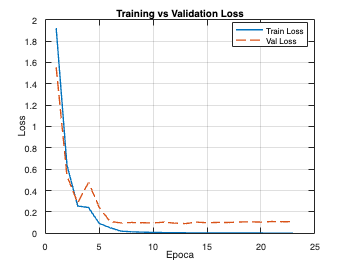



% --- Plot Training vs Validation Loss ---
figure('Name','Loss: Training vs Validation','NumberTitle','off');
plot(1:epoch, loss_history(1:epoch), '-' , 'LineWidth',1.5); hold on;
plot(1:epoch, val_loss_hist(1:epoch), '--', 'LineWidth',1.5);
xlabel('Epoca');
ylabel('Loss');
title('Training vs Validation Loss');
legend('Train Loss','Val Loss','Location','best');
grid on;

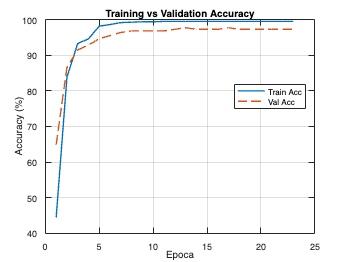


% --- Plot Training vs Validation Accuracy ---
figure('Name','Accuracy: Training vs Validation','NumberTitle','off');
plot(1:epoch, acc_history(1:epoch), '-' , 'LineWidth',1.5); hold on;
plot(1:epoch, val_acc_hist(1:epoch), '--', 'LineWidth',1.5);
xlabel('Epoca');
ylabel('Accuracy (%)');
title('Training vs Validation Accuracy');
legend('Train Acc','Val Acc','Location','best');
grid on;



%% 7) TEST ----------------------------------------------------------------
[filters1,bias1,filters2,bias2,filters3,bias3,W_fc,b_fc] = best{:};
correct_test = 0;  N_test = size(imgs_test,3);

for i = 1:N_test
    x = imgs_test(:,:,i);
    [c1,~] = conv2d_forward(x,filters1,bias1); r1=max(c1,0);
    [p1,~] = maxpool2d_forward(r1,pool);
    [c2,~] = conv2d_forward_multi(p1,filters2,bias2); r2=max(c2,0);
    [p2,~] = maxpool2d_forward(r2,pool);
    [c3,~] = conv2d_forward_multi(p2,filters3,bias3); r3=max(c3,0);
    [p3,~] = maxpool2d_forward(r3,pool);
    z = W_fc*reshape(p3,[],1)+b_fc;  z=z-max(z);  y_pred = exp(z)/sum(exp(z));
    if find(y_pred==max(y_pred)) == y_test(i); correct_test = correct_test + 1; end
end
fprintf('\n*** TEST ACCURACY: %.2f %% ***\n', correct_test / N_test * 100);


*** TEST ACCURACY: 86.67 % ***




fprintf('>>> Fine script (totale %.2f s)\n', toc);

>>> Fine script (totale 13150.70 s)


## 8) SUPPORT FUNCTIONS

function Y = onehot_encode(labels, num_classes)
    labels = labels(:)';               % vettore riga
    N = numel(labels);
    Y = zeros(num_classes, N);
    idx = sub2ind(size(Y), labels, 1:N);
    Y(idx) = 1;
end

function dx = maxpool2d_backward(dout, mask)
% BACKWARD del max-pooling (maschere = cell array binarie)
    F = numel(mask);
    [H,W]   = size(mask{1});
    [Hp,Wp] = size(dout(:,:,1));
    ph = floor(H/Hp);  pw = floor(W/Wp);
    dx = zeros(H,W,F);
    for f = 1:F
        m = mask{f};  d = dout(:,:,f);
        for i = 1:Hp
            for j = 1:Wp
                rs = (i-1)*ph+1; re = i*ph;
                cs = (j-1)*pw+1; ce = j*pw;
                dx(rs:re, cs:ce, f) = m(rs:re, cs:ce) * d(i,j);
            end
        end
    end
end


